%% SECTION 1 — Import and Split Data
FranceData = readtable("FranceDatawithPop.csv");


% Convert 'Year' to datetime
FranceData.Year = datetime(FranceData.Year, 1, 1);


% Convert to timetable
FranceTT = table2timetable(FranceData, "RowTimes", "Year");


% Split into training and test sets (e.g., last 20 years as test)
selectedCut = datetime(2018, 1, 1);
trainData = FranceTT(FranceTT.Year < selectedCut, :);
testData  = FranceTT(FranceTT.Year >= selectedCut, :);


fprintf("✅ Height of training data: %d\n", height(trainData));

✅ Height of training data: 208


fprintf("✅ Height of test data: %d\n", height(testData));

✅ Height of test data: 6


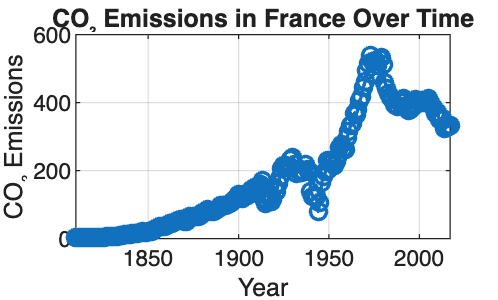



% Visualize raw data
figure;
plot(trainData.Year, trainData.Total, '-o', 'LineWidth', 1.3)
grid on
title("CO₂ Emissions in France Over Time")
xlabel("Year")
ylabel("CO₂ Emissions")



% Save for next sections
save('Section1_France.mat', 'trainData', 'testData', 'selectedCut');


%% SECTION 2 — Transform & Check Stationarity
load('Section1_France.mat');


% Check for trend/stationarity
y = trainData.Total;
h = adftest(y);
if h == 0
   disp('Series is NOT stationary (trend present).')
else
   disp('Series is stationary.')
end

Series is NOT stationary (trend present).




% Log transform to stabilize variance
trainData.logTotal = log(trainData.Total + 1);


% Test stationarity on log and differenced log
[h_log, p_log] = adftest(trainData.logTotal);
[h_diff, p_diff] = adftest(diff(trainData.logTotal));


fprintf('ADF (log): h=%d, p=%.4f\n', h_log, p_log);

ADF (log): h=0, p=0.9962


fprintf('ADF (diff log): h=%d, p=%.4f\n', h_diff, p_diff);

ADF (diff log): h=1, p=0.0010




if h_diff == 1
   disp('✅ The differenced log-transformed data is stationary.');
else
   disp('⚠️ Data may need more differencing.');
end

✅ The differenced log-transformed data is stationary.




save('Section2_France.mat', 'trainData', 'testData', 'selectedCut');


% SECTION 3
% Define number of segments
numSegments = 6;

% Get numeric years from timetable
years = year(trainData.Year);

% Compute equally spaced breakpoints (inclusive)
edges = round(linspace(min(years), max(years), numSegments+1));

segments = cell(numSegments,1);
for i = 1:numSegments
    startYr = edges(i);
    endYr   = edges(i+1);
    seg = trainData(trainData.Year >= datetime(startYr,1,1) & ...
                    trainData.Year < datetime(endYr,1,1), :);
    if isempty(seg)
        fprintf('⚠️ Segment %d is empty (%d–%d)\n', i, startYr, endYr);
    else
        segments{i} = seg;
        fprintf('✅ Segment %d has %d observations (%d–%d)\n', ...
                 i, height(seg), startYr, endYr);
    end
end

✅ Segment 1 has 35 observations (1810–1845)
✅ Segment 2 has 34 observations (1845–1879)
✅ Segment 3 has 35 observations (1879–1914)
✅ Segment 4 has 34 observations (1914–1948)
✅ Segment 5 has 35 observations (1948–1983)
✅ Segment 6 has 34 observations (1983–2017)


%% SECTION 4 — Fit and Plot Piecewise Models
load('Section2_France.mat');  % Load training data

% Make sure segments from Section 3 are available
if ~exist('segments', 'var')
    warning('Segments not found. Please run Section 3 first.');
end

figure;
hold on;
colors = lines(length(segments));  % Distinct colors per segment
models = cell(length(segments), 1); % Store fitted models

for i = 1:length(segments)
    seg = segments{i};
    if isempty(seg) || height(seg) < 10
        fprintf('⚠️ Segment %d skipped (too few observations).\n', i);
        continue;
    end

    % Define predictor (time) and response (log-transformed CO2)
    x = year(seg.Year);
    y = seg.logTotal;

    % Fit a linear model (simple example, changeable)
    mdl = fitlm(x, y);
    models{i} = mdl;

    % Get fitted values for plotting
    yhat = predict(mdl, x);

    % Plot actual data and fitted line
    plot(seg.Year, y, 'o', 'Color', colors(i,:), 'MarkerFaceColor', colors(i,:)*0.5, ...
         'DisplayName', sprintf('Segment %d data', i));
    plot(seg.Year, yhat, '-', 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', sprintf('Segment %d fit', i));

    % Display summary info
    fprintf("✅ Segment %d: slope = %.4f, R² = %.3f, n = %d\n", ...
        i, mdl.Coefficients.Estimate(2), mdl.Rsquared.Ordinary, height(seg));
end

✅ Segment 1: slope = 0.0557, R² = 0.966, n = 35
✅ Segment 2: slope = 0.0433, R² = 0.935, n = 34
✅ Segment 3: slope = 0.0240, R² = 0.974, n = 35
✅ Segment 4: slope = 0.0031, R² = 0.011, n = 34
✅ Segment 5: slope = 0.0315, R² = 0.908, n = 35
✅ Segment 6: slope = -0.0050, R² = 0.489, n = 34


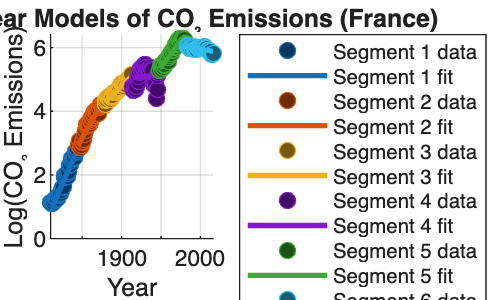


grid on;
xlabel('Year');
ylabel('Log(CO₂ Emissions)');
title('Piecewise Linear Models of CO₂ Emissions (France)');
legend('show', 'Location', 'bestoutside');
hold off;


% Save models for later analysis
save('Section4_France_Models.mat', 'models', 'segments');


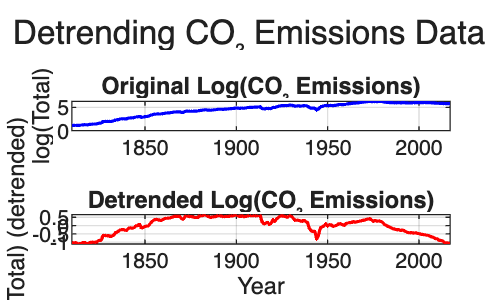


%% Detrend CO₂ data (log-transformed)
load('Section2_France.mat', 'trainData');

% Log-transform first (helps stabilize variance)
yLog = log(trainData.Total + 1);

% Detrend the log-transformed series
yDetrend = detrend(yLog);

% Add to your training table
trainData.logTotal_detrend = yDetrend;

% Visualize before and after
figure;
subplot(2,1,1);
plot(trainData.Year, yLog, 'b-', 'LineWidth', 1.2);
title('Original Log(CO₂ Emissions)');
ylabel('log(Total)');
grid on;

subplot(2,1,2);
plot(trainData.Year, yDetrend, 'r-', 'LineWidth', 1.2);
title('Detrended Log(CO₂ Emissions)');
xlabel('Year');
ylabel('log(Total) (detrended)');
grid on;

sgtitle('Detrending CO₂ Emissions Data');

%% Corrected SECTION 5 — Forecast True Test Period (2018–2023)
load('Section2_France.mat', 'trainData', 'testData');

% Define ARIMA configurations
arimaConfigs = {
    arima(1,1,0), ...
    arima(1,1,1), ...
    arima(2,1,2)
};
modelNames = ["ARIMA(1,1,0)", "ARIMA(1,1,1)", "ARIMA(2,1,2)"];

% Prepare test data
yTest = log(testData.Total + 1);
horizon = height(testData);

% Preallocate results
RMSE = nan(length(modelNames),1);
forecastResults = cell(length(modelNames),1);

figure; hold on;
colors = lines(length(modelNames));

% Log-transform full training data
yTrain = log(trainData.Total + 1);

for j = 1:length(arimaConfigs)
    fprintf('\n=== Testing %s on 2018–2023 ===\n', modelNames(j));
    try
        % Fit ARIMA on all training data (up to 2017)
        mdl = estimate(arimaConfigs{j}, yTrain, 'Display', 'off');

        % Forecast test period
        [yhat_log, ~] = forecast(mdl, horizon, 'Y0', yTrain);
        yhat = exp(yhat_log) - 1;  % back-transform
        forecastResults{j} = yhat;

        % Compute RMSE on *actual test data*
        rmse = sqrt(mean((yhat - testData.Total).^2));
        RMSE(j) = rmse;

        fprintf('✅ RMSE (Test 2018–2023): %.4f\n', rmse);

        % Plot predictions vs actual
        plot(testData.Year, yhat, '-', 'LineWidth', 2, ...
             'Color', colors(j,:), ...
             'DisplayName', sprintf('%s (RMSE=%.3f)', modelNames(j), rmse));
    catch ME
        fprintf('⚠️ %s failed: %s\n', modelNames(j), ME.message);
    end
end


=== Testing ARIMA(1,1,0) on 2018–2023 ===


✅ RMSE (Test 2018–2023): 72.1699



=== Testing ARIMA(1,1,1) on 2018–2023 ===


✅ RMSE (Test 2018–2023): 72.1335



=== Testing ARIMA(2,1,2) on 2018–2023 ===


✅ RMSE (Test 2018–2023): 70.9764


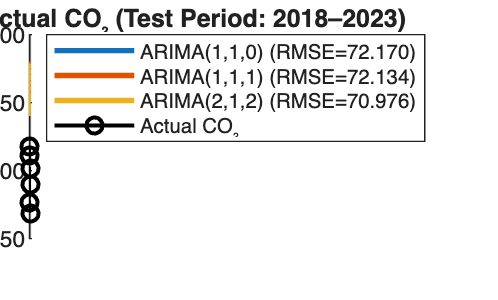


% Plot actual data
plot(testData.Year, testData.Total, 'ko-', 'LineWidth', 1.5, 'DisplayName','Actual CO₂');

xlabel('Year');
ylabel('CO₂ Emissions (metric tons)');
title('ARIMA Model Forecasts vs Actual CO₂ (Test Period: 2018–2023)');
legend('Location','bestoutside');
grid on;
hold off;


% Display summary
results = table(modelNames', RMSE, 'VariableNames', {'Model','RMSE'});
disp('===== Test-Period RMSE Results =====');

===== Test-Period RMSE Results =====


disp(results);

        Model          RMSE 
    ______________    ______

    "ARIMA(1,1,0)"     72.17
    "ARIMA(1,1,1)"    72.134
    "ARIMA(2,1,2)"    70.976



%% SECTION 6 — Plot Full Range (1810–2023) and Test Range (2018–2023)
load('Section2_France.mat', 'trainData', 'testData');

% Combine full range of years
allYears = [trainData.Year; testData.Year];
allCO2   = [trainData.Total; testData.Total];

% Log-transform training data for ARIMA modeling
yTrain = log(trainData.Total + 1);

% Reuse ARIMA configurations
arimaConfigs = {
    arima(1,1,0), ...
    arima(1,1,1), ...
    arima(2,1,2)
};
modelNames = ["ARIMA(1,1,0)", "ARIMA(1,1,1)", "ARIMA(2,1,2)"];

colors = lines(length(modelNames));
forecastResultsFull = cell(length(modelNames),1);

figure; hold on;

for j = 1:length(arimaConfigs)
    fprintf('\n=== Full-range visualization for %s ===\n', modelNames(j));
    try
        % Fit model on all available training data (1810–2017)
        mdl = estimate(arimaConfigs{j}, yTrain, 'Display', 'off');

        % Forecast for 2018–2023
        horizon = height(testData);
        [yhat_log, ~] = forecast(mdl, horizon, 'Y0', yTrain);
        yhat = exp(yhat_log) - 1;  % back-transform

        % ✅ Get fitted values correctly
        fittedLog = yTrain - infer(mdl, yTrain);
        fitted = exp(fittedLog) - 1;

        % Plot fitted line (training)
        plot(trainData.Year, fitted, '-', 'LineWidth', 1.5, ...
            'Color', colors(j,:), ...
            'DisplayName', sprintf('%s (Fitted)', modelNames(j)));

        % Plot forecast line (test)
        plot(testData.Year, yhat, '--', 'LineWidth', 2.2, ...
            'Color', colors(j,:), ...
            'DisplayName', sprintf('%s (Forecast)', modelNames(j)));

    catch ME
        fprintf('⚠️ %s failed: %s\n', modelNames(j), ME.message);
    end
end


=== Full-range visualization for ARIMA(1,1,0) ===

=== Full-range visualization for ARIMA(1,1,1) ===

=== Full-range visualization for ARIMA(2,1,2) ===


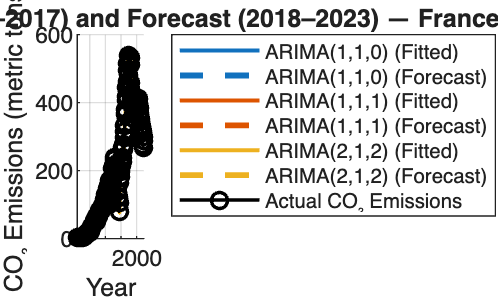


% Actual data for reference
plot(allYears, allCO2, 'k-o', 'LineWidth', 1.3, ...
    'DisplayName', 'Actual CO₂ Emissions');

xlabel('Year');
ylabel('CO₂ Emissions (metric tons)');
title('ARIMA Model Fit (1810–2017) and Forecast (2018–2023) — France');
legend('Location','bestoutside');
grid on;
hold off;

%% SECTION 6.5 — Fit ARIMA Models
model1 = estimate(arima(1,1,1), trainData.Total);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.36315       0.39718        0.91432         0.36055
    AR{1}        0.77545       0.10308         7.5225      5.3723e-14
    MA{1}       -0.65522       0.12206        -5.3682      7.9536e-08
    Variance      203.12        11.627          17.47      2.4167e-68



model2 = estimate(arima(2,1,2), trainData.Total);

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.67885       0.83882        0.80929         0.41835
    AR{1}       -0.18391       0.12828        -1.4337         0.15166
    AR{2}         0.7611       0.10402         7.3169      2.5375e-13
    MA{1}        0.31514       0.14213         2.2172        0.026612
    MA{2}       -0.66054       0.12847        -5.1415      2.7258e-07
    Variance      202.29        11.829         17.101      1.4582e-65



model3 = estimate(arima(0,1,1), trainData.Total);

 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     1.5658         1.136         1.3783          0.1681
    MA{1}       0.12163       0.04662          2.609        0.009081
    Variance     207.04         12.16         17.026      5.2493e-65



model4 = estimate(arima(1,1,2), trainData.Total);

 
    ARIMA(1,1,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.38254       0.48375        0.79077         0.42908
    AR{1}        0.76345       0.17236         4.4294      9.4509e-06
    MA{1}        -0.6498       0.16942        -3.8355      0.00012532
    MA{2}       0.012191      0.070896        0.17196         0.86347
    Variance       203.1        11.866         17.116        1.12e-65



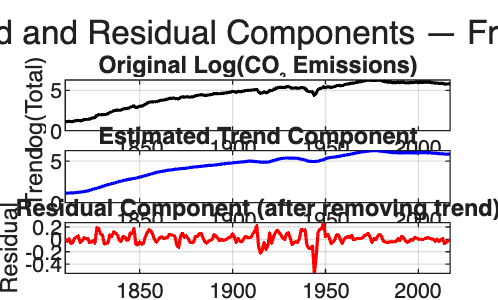

%% SECTION 7 — Decomposition, Residual Diagnostics, Model Comparison with Test RMSE

% Log-transform training data
yTrain = log(trainData.Total + 1);

% Log-transform test data
yTest = log(testData.Total + 1);
horizon = height(testData);

%% (1) Trend and residual decomposition
trend = movmean(yTrain, 10, 'omitnan');       % moving average trend
residuals = yTrain - trend;                  % detrended residuals

figure;
subplot(3,1,1);
plot(trainData.Year, yTrain, 'k', 'LineWidth', 1.2);
title('Original Log(CO₂ Emissions)'); ylabel('log(Total)'); grid on;

subplot(3,1,2);
plot(trainData.Year, trend, 'b', 'LineWidth', 1.2);
title('Estimated Trend Component'); ylabel('Trend'); grid on;

subplot(3,1,3);
plot(trainData.Year, residuals, 'r', 'LineWidth', 1.2);
title('Residual Component (after removing trend)'); ylabel('Residual'); xlabel('Year'); grid on;

sgtitle('Trend and Residual Components — France');

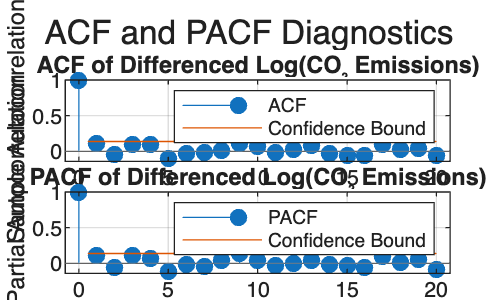


%% (2) ACF and PACF of differenced log series
yDiff = diff(yTrain);

figure;
subplot(2,1,1);
autocorr(yDiff);
title('ACF of Differenced Log(CO₂ Emissions)');

subplot(2,1,2);
parcorr(yDiff);
title('PACF of Differenced Log(CO₂ Emissions)');
sgtitle('ACF and PACF Diagnostics');


%% (3) Fit ARIMA models and compute AIC/BIC, Train RMSE, Test RMSE
arimaConfigs = {arima(1,1,0), arima(1,1,1), arima(2,1,2)};
modelNames = ["ARIMA(1,1,0)","ARIMA(1,1,1)","ARIMA(2,1,2)"];

modelResults = cell(length(arimaConfigs),1);
aic = zeros(length(arimaConfigs),1);
bic = zeros(length(arimaConfigs),1);
rmseTrain = zeros(length(arimaConfigs),1);
rmseTest = zeros(length(arimaConfigs),1);

for j = 1:length(arimaConfigs)
    % Fit model and get log-likelihood
    [mdl,~,logL] = estimate(arimaConfigs{j}, yTrain, 'Display','off');
    modelResults{j} = mdl;

    % Infer residuals for training RMSE
    res = infer(mdl, yTrain);
    rmseTrain(j) = sqrt(mean(res.^2));

    % Forecast test period
    [yhat_log, ~] = forecast(mdl, horizon, 'Y0', yTrain);
    yhat = exp(yhat_log) - 1;  % back-transform to original scale

    % Compute test RMSE on actual CO₂ values
    rmseTest(j) = sqrt(mean((yhat - testData.Total).^2));

    % Count estimated parameters: AR + MA + constant + variance
    numParams = numel(mdl.P) + numel(mdl.Q) + double(~isempty(mdl.Constant)) + double(~isempty(mdl.Variance));

    % Compute AIC and BIC manually
    n = length(yTrain);
    aic(j) = -2*logL + 2*numParams;
    bic(j) = -2*logL + numParams*log(n);
end

% Display summary table with Train and Test RMSE
modelSummary = table(modelNames', aic, bic, rmseTrain, rmseTest, ...
    'VariableNames',{'Model','AIC','BIC','Train_RMSE','Test_RMSE'});
disp('===== ARIMA Model Fit Summary =====');

===== ARIMA Model Fit Summary =====


disp(modelSummary);

        Model           AIC        BIC      Train_RMSE    Test_RMSE
    ______________    _______    _______    __________    _________

    "ARIMA(1,1,0)"    -409.11    -395.76      0.08878       72.17  
    "ARIMA(1,1,1)"    -410.07    -396.72     0.088573      72.134  
    "ARIMA(2,1,2)"    -410.65     -397.3     0.088451      70.976  




%% (4) Identify best model by AIC
[~, bestIdx] = min(aic);
bestModel = modelResults{bestIdx};
bestModelName = modelNames(bestIdx);
disp(['✅ Best model by AIC: ', bestModelName]);

    "✅ Best model by AIC: "    "ARIMA(2,1,2)"



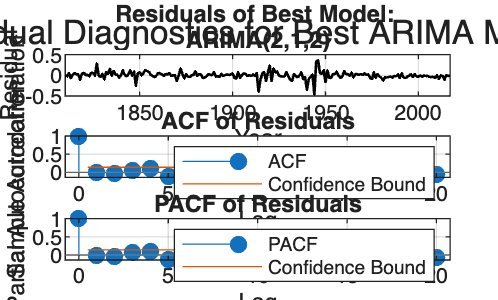


% Compute residuals for best model
resBest = infer(bestModel, yTrain);

% Align years with residuals (accounts for differencing)
years_res = trainData.Year(end - length(resBest) + 1 : end);

%% (5) Plot residual diagnostics
figure;
subplot(3,1,1);
plot(years_res, resBest, 'k', 'LineWidth', 1);
xlabel('Year'); ylabel('Residual');
title(['Residuals of Best Model: ', bestModelName]); grid on;

subplot(3,1,2);
autocorr(resBest);
title('ACF of Residuals');

subplot(3,1,3);
parcorr(resBest);
title('PACF of Residuals');
sgtitle('Residual Diagnostics for Best ARIMA Model');

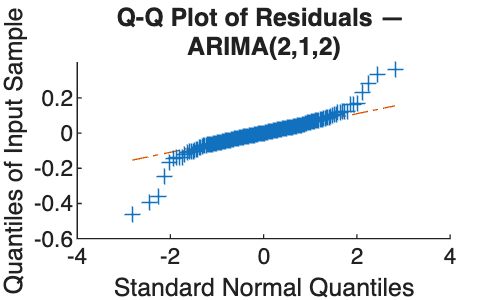


%% (6) Q-Q plot of residuals
figure;
qqplot(resBest);
title(['Q-Q Plot of Residuals — ', bestModelName]);

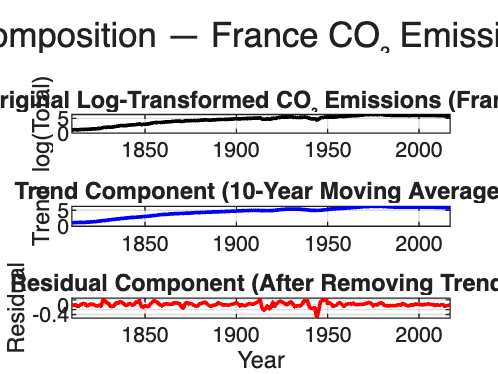



%Plotting the decomposition
% Apply a moving average smoother (10-year window)
trendComponent = movmean(yTrain, 10, 'omitnan');

% Compute the residual (detrended) component
residualComponent = yTrain - trendComponent;

% Plot the decomposition
figure('Color', 'w', 'Position', [100 100 800 600]);

subplot(3,1,1);
plot(trainData.Year, yTrain, 'k', 'LineWidth', 1.4);
title('Original Log-Transformed CO₂ Emissions (France)');
ylabel('log(Total)');
grid on;

subplot(3,1,2);
plot(trainData.Year, trendComponent, 'b', 'LineWidth', 1.4);
title('Trend Component (10-Year Moving Average)');
ylabel('Trend');
grid on;

subplot(3,1,3);
plot(trainData.Year, residualComponent, 'r', 'LineWidth', 1.4);
title('Residual Component (After Removing Trend)');
xlabel('Year');
ylabel('Residual');
grid on;

sgtitle('Time Series Decomposition — France CO₂ Emissions (1810–2018)');